# 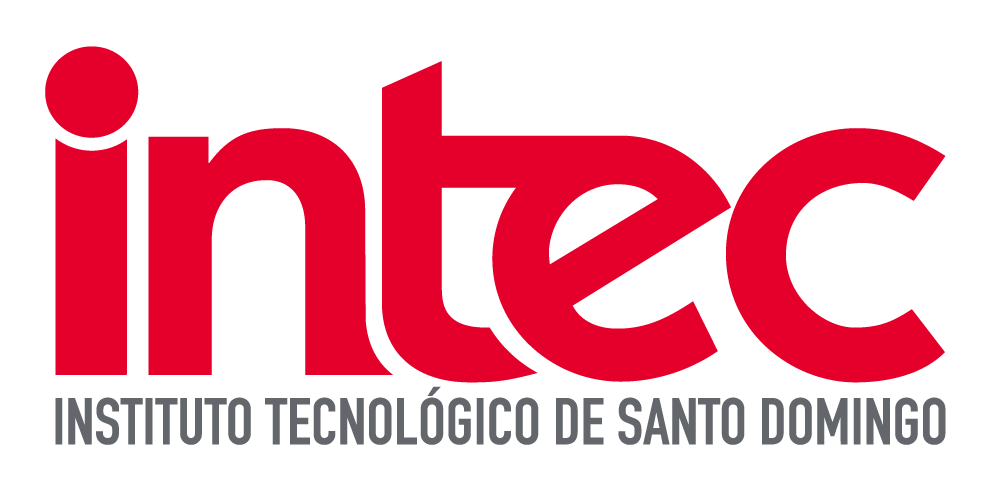

# Comprensión de funciones de transferencia

Autor(a): Miguel Euclides Aybar Mejía, Instituto Tecnológico de Santo Domingo (INTEC)

## Resumen

Esta actividad presenta una serie de problemas prácticos para reforzar la comprensión de las funciones de transferencia y su análisis utilizando MATLAB. Los estudiantes modelarán sistemas dinámicos, analizarán su comportamiento en frecuencia y aplicarán conceptos como la respuesta al escalón y al impulso*.*

*Palabras claves: Sistema de Control, Ingeniería Eléctrica, Transformada Laplace, Ingeniería Eléctronica, Ingeniería Mecatrónica. *

## Objetivos de Aprendizaje

Al completar esta actividad, los estudiantes podrán:

- Representar sistemas dinámicos como funciones de transferencia en MATLAB.

- Analizar la respuesta en frecuencia de sistemas de control utilizando herramientas de MATLAB.

- Obtener e Iustrar la respuesta al escalón, rampa, al impulso y señal Sinuosoidal de un sistema de control utilizando MATLAB.

- Interpretar los resultados obtenidos en términos del comportamiento del sistema físico.

## Antes de empezar 

#### **Prerrequisitos** 

- Conocimientos básicos de MATLAB, incluyendo la creación de scripts, variables y representación gráfica.

- Comprensión fundamental de conceptos de sistemas de control, como la transformada de Laplace y la representación de sistemas en el dominio de la frecuencia

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Sección 1: Conceptos 

 En MATLAB, las funciones clc y clear se utilizan para limpiar la ventana de comandos y las variables de la memoria de trabajo, respectivamente.

clc
clear


En MATLAB, las funciones clc y clear se utilizan para limpiar la ventana de comandos y las variables de la memoria de trabajo, respectivamente.

**¿Qué es una función de transferencia?**

En el ámbito de la ingeniería de control y sistemas dinámicos, la función de transferencia representa el comportamiento en el dominio de la frecuencia de un sistema lineal invariante en el tiempo (LTI). Se define como la relación matemática entre la transformada de Laplace de la salida del sistema y la transformada de Laplace de la entrada. En otras palabras, la función de transferencia describe cómo el sistema responde a diferentes señales de entrada en el dominio de la frecuencia.

**¿Cómo se expresa la función de transferencia?**

La función de transferencia se expresa típicamente como una fracción de polinomios en el dominio de la frecuencia, es decir, una relación entre dos polinomios en la variable s (la variable de Laplace). La forma general de una función de transferencia es:

$G\left(s\right)=\frac{N\left(S\right)}{D\left(s\right)}$, donde:

- **N(s)** es el numerador, que representa el polinomio de la salida.

- **D(s)** es el denominador, que representa el polinomio de la entrada.

## Función de transferencia: Concepto y simulación en MATLAB

¿Qué es una función de transferencia?

En el ámbito de la ingeniería de control y sistemas dinámicos, la **función de transferencia** representa el comportamiento en el dominio de la frecuencia de un sistema lineal invariante en el tiempo (LTI). Se define como la relación matemática entre la transformada de Laplace de la salida del sistema y la transformada de Laplace de la entrada. En otras palabras, la función de transferencia describe cómo el sistema responde a diferentes señales de entrada en el dominio de la frecuencia.

**¿Cómo se expresa la función de transferencia?**

La función de transferencia se expresa típicamente como una fracción de polinomios en el dominio de la frecuencia, es decir, una relación entre dos polinomios en la variable `s` (la variable de Laplace). La forma general de una función de transferencia es:

`G(s) = N(s) / D(s)`

Donde:

- **N(s)** es el numerador, que representa el polinomio de la salida.

- **D(s)** es el denominador, que representa el polinomio de la entrada.

**¿Qué información proporciona la función de transferencia?**

La función de transferencia proporciona información valiosa sobre el comportamiento dinámico del sistema, incluyendo:

- **Ganancia:** La magnitud de la respuesta del sistema a diferentes frecuencias de entrada.

- **Fase:** El desfase de la respuesta del sistema con respecto a la entrada.

- **Ancho de banda:** El rango de frecuencias en las que el sistema tiene una respuesta significativa.

- **Estabilidad:** La capacidad del sistema para alcanzar un estado de equilibrio estable.

**Cómo se simula una función de transferencia en MATLAB?**

MATLAB ofrece diversas herramientas para simular y analizar funciones de transferencia. Algunas de las funciones más comunes incluyen:

- [`tf`](https://la.mathworks.com/help/control/ref/tf.html?searchHighlight=Tf&s_tid=srchtitle_support_results_1_Tf)

- [`bode`](https://la.mathworks.com/help/control/ref/dynamicsystem.bode.html?searchHighlight=bode&s_tid=srchtitle_support_results_1_bode)

- [`step`](https://la.mathworks.com/help/control/ref/dynamicsystem.step.html?searchHighlight=step&s_tid=srchtitle_support_results_2_step)

- [`impulse`](https://la.mathworks.com/help/control/ref/dynamicsystem.impulse.html)

- [`feedback`](https://la.mathworks.com/help/control/ug/using-feedback-to-close-feedback-loops.html)

- [**lsim**](https://la.mathworks.com/help/control/ref/dynamicsystem.lsim.html)**: **

## Sección 2: Ejemplo 1 

Defina la siguiente función de transferencia $G=\frac{S-2}{S^2 +3S+2}$ , grafique su comportamiento en Bode, al escalón, y el impulso

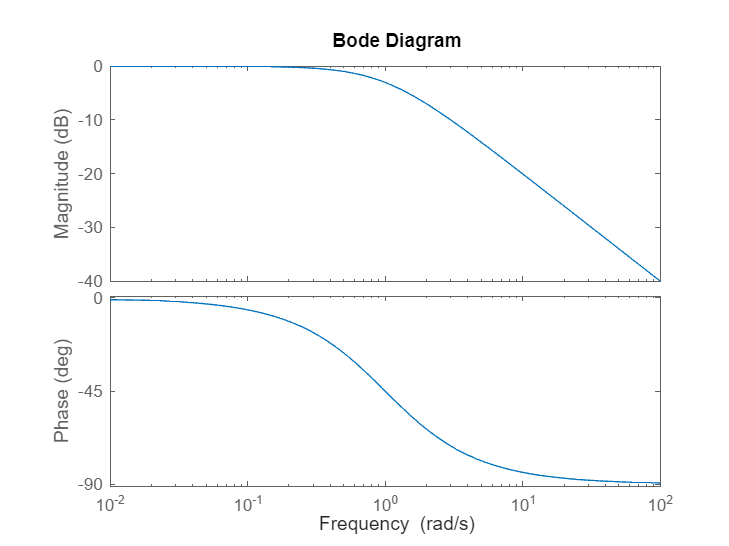

% Definir la función de transferencia
G = tf([1 2],[1 3 2]);

% Generar diagrama de Bode
bode(G);

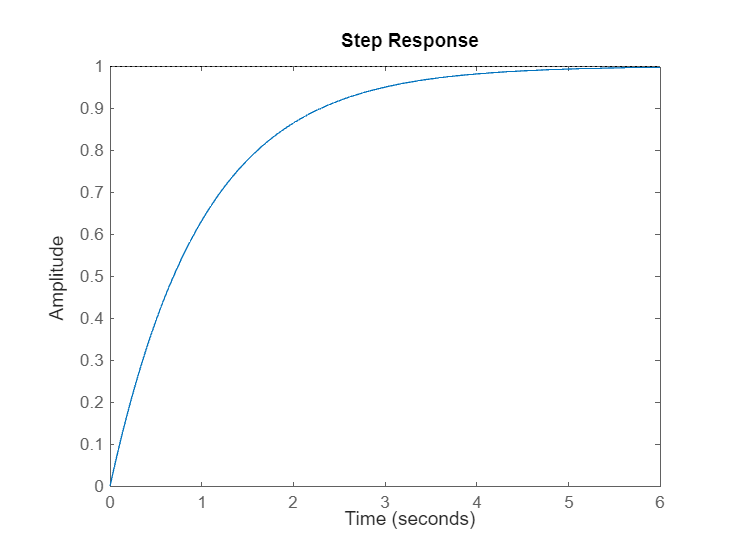


% Simular respuesta escalón
step(G);

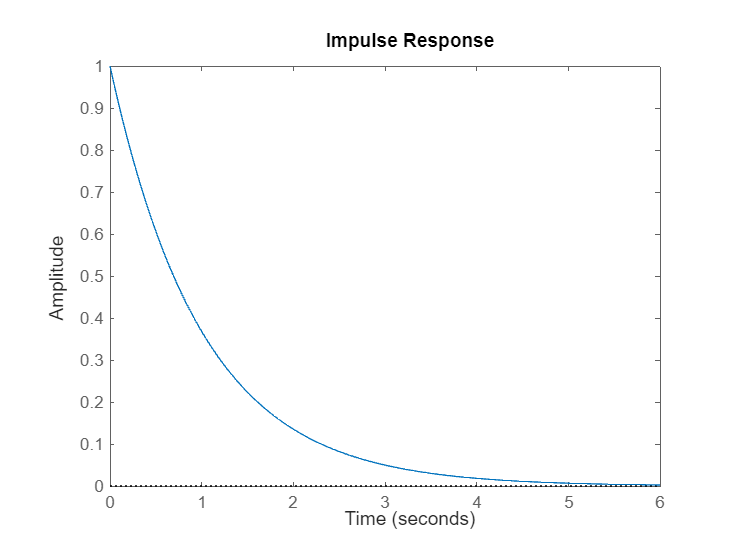


% Simular respuesta impulso
impulse(G);

**Este ejercicio enseña sobre analísis de funciones de transferencias y estabilidad segun criterio de los polos, ceros y bode. La descripcion del problema y los ejercicios a calificar se proporcionan abajo. **

### **a. **Estabilidad de un Sistema de Control por Ubicación de Polos y Ceros  

En el análisis de sistemas de control lineal invariante en el tiempo (LTI), la **ubicación de los polos y ceros** en el **plano complejo** proporciona información crucial sobre la **estabilidad del sistema**. La estabilidad se refiere a la capacidad del sistema para alcanzar un estado de equilibrio estable en respuesta a una entrada o perturbación.

**Relación entre polos, ceros y estabilidad:**

- **Polos:** Representan las raíces de la ecuación característica del sistema. Si todos los polos se encuentran dentro del **círculo unitario** en el plano complejo, el sistema se considera **estable**. Si al menos un polo se ubica **fuera del círculo unitario**, el sistema se considera **inestable**.

- **Ceros:** Representan los valores de la variable de entrada para los cuales la salida del sistema es nula. Los ceros no tienen un impacto directo en la estabilidad del sistema, pero pueden influir en la respuesta transiente y la velocidad de convergencia a un estado estable.

**Observación de la estabilidad en el plano complejo:**

- **Polos dentro del círculo unitario:** Indican que la respuesta del sistema a cualquier entrada o perturbación tenderá a cero con el tiempo, es decir, el sistema es **estable**.

- **Polos sobre el círculo unitario:** Indican que la respuesta del sistema a ciertas entradas o perturbaciones oscilará con una magnitud constante, es decir, el sistema está en el **límite de la estabilidad**.

- **Polos fuera del círculo unitario:** Indican que la respuesta del sistema a cualquier entrada o perturbación crecerá exponencialmente con el tiempo, es decir, el sistema es **inestable**.

### **b. Estabildiad del sistema de control en diagrama de BODE: magnitud y Fase  **

El **diagrama de Bode** es una herramienta gráfica fundamental para analizar la **estabilidad de un sistema de control en lazo cerrado**. A través de la observación de la **magnitud** y la **fase** de la función de transferencia en diferentes frecuencias, se puede determinar si el sistema presentará un comportamiento estable o inestable.

**Aspectos a observar en el diagrama de Bode para determinar la estabilidad:**

**Magnitud:**

- **Margen de ganancia:** Se define como la distancia en decibelios (dB) entre la curva de magnitud de la función de transferencia abierta (bucle abierto) y la línea de 0 dB (unidad) en la frecuencia de cruce (donde la fase es -180°). Un margen de ganancia positivo indica estabilidad, mientras que un margen de ganancia negativo indica inestabilidad.

- **Frecuencia de cruce:** Es la frecuencia en la que la magnitud de la función de transferencia abierta cruza la línea de 0 dB. Un valor bajo de la frecuencia de cruce puede sugerir una mayor tendencia a la inestabilidad.

**Fase:**

- **Margen de fase:** Se define como la diferencia en grados entre la fase de la función de transferencia abierta y la línea de -180° en la frecuencia de cruce. Un margen de fase positivo indica estabilidad, mientras que un margen de fase negativo o nulo indica inestabilidad.

- **Fase a baja frecuencia:** La fase de la función de transferencia abierta a baja frecuencia debe ser cercana a 0° para garantizar un buen seguimiento en estado estacionario.

**Criterios generales de estabilidad:**

- **Sistema estable:** Margen de ganancia positivo, margen de fase positivo, fase a baja frecuencia cercana a 0°.

- **Sistema inestable:** Margen de ganancia negativo, margen de fase negativo o nulo, fase a baja frecuencia alejada de 0°.

**Consideraciones adicionales:**

- La presencia de picos de resonancia en la curva de magnitud puede indicar una mayor tendencia a la inestabilidad.

- La fase a alta frecuencia no suele tener un impacto significativo en la estabilidad en lazo cerrado. 

**Descripción del Problema:**  Para las siguientes ecuaciones describa un programa  que analice las siguientes funciones de transferencia :

           Función_de_Transferencia1                                                   Función_de_Transferencia2                                        Función_de_Transferencia3

**COMANDOS ÚTILES:** [plot](https://la.mathworks.com/help/matlab/ref/plot.html), [real](https://la.mathworks.com/help/matlab/ref/real.html),[ imag](https://la.mathworks.com/help/matlab/ref/imag.html?s_tid=doc_ta), [roots](https://la.mathworks.com/help/matlab/ref/roots.html?searchHighlight=Roots&s_tid=srchtitle_support_results_1_Roots), [solve](https://la.mathworks.com/help/symbolic/sym.solve.html?searchHighlight=Solve&s_tid=srchtitle_support_results_1_Solve), [sym](https://la.mathworks.com/help/symbolic/sym.html?searchHighlight=sym&s_tid=srchtitle_support_results_2_sym), [subplot,](https://la.mathworks.com/help/matlab/ref/subplot.html?searchHighlight=subplot%2C&s_tid=srchtitle_support_results_1_subplot%252C) [tf2zp](https://la.mathworks.com/help/signal/ref/tf2zp.html?searchHighlight=tf2zp&s_tid=srchtitle_support_results_1_tf2zp), [zplane](https://la.mathworks.com/help/signal/ref/zplane.html?searchHighlight=zplane&s_tid=srchtitle_support_results_1_zplane), [conv](https://la.mathworks.com/help/matlab/ref/conv.html?searchHighlight=Conv&s_tid=srchtitle_support_results_1_Conv), … Los comandos útiles que no estén indicados aquí deberán ser investigados por el estudiante [sugerencia: utilizar función [help](https://la.mathworks.com/help/matlab/ref/help.html?searchHighlight=Help&s_tid=srchtitle_support_results_1_Help)].

Para cada función de transferencia:

- Declare las raices de los numeradores y denominadores 

- Declare la funciones de transferencia

- Declare el valor de los polos y ceros de cada función de transferencia

- Declare en el plano o eje los polos y ceros de cada ecuación

- Encuentre la solución a cada ecuación

- Grafique el comportamiento al Escalón (step), Impulso (Impulse), rampa, senoida. 

- Grafique el comportamiento en lazo abierto y en lazo cerrado de cada función de transferencia 

- Haga que todos los graficos aparezcan en una sola pantalla con sus nombre cada uno

## Sección 3: Ejercicio 2

Declare el codigo para lograr desarrollar las tres funciones de transferencias ( Función_de_Transferencia1,  Función_de_Transferencia2,  Función_de_Transferencia3) y detecte con sus respuestas y represetación en el plano si es estable o inestable.

Declare tambien el comportamiento de las mismas fuciones en lazo abiero y lazo cerrado y grafiquelas en una sola ventana que se grafique todo, con nombre de cada una. 

% Celda para adicionar código

## Recursos Adicionales

En esta sección comparta enlaces o referencias adicionales para los educadores y estudiantes que usen este material.

- **Documentación de MATLAB sobre funciones de transferencia:** [https://www.mathworks.com/Links to an external site.](https://www.mathworks.com/)

- **Comunidad de MATLAB**: [https://la.mathworks.com/matlabcentral/?s_tid=gn_mlcLinks to an external site.](https://la.mathworks.com/matlabcentral/?s_tid=gn_mlc)

- **Tutoriales de MATLAB sobre análisis de sistemas de control:** [https://www.mathworks.com/products/simulink-online.htmlLinks to an external site.](https://www.mathworks.com/products/simulink-online.html)

- **Video tutorial: Análisis de funciones de transferencia de segundo orden usando MATLAB:** [https://m.youtube.com/watch?v=lJHDp2xWbsALinks to an external site.](https://m.youtube.com/watch?v=lJHDp2xWbsA)

- **Artículo: Introducción a las funciones de transferencia y su análisis en MATLAB:** [https://www.tutorialspoint.com/control_systems/control_systems_quick_guide.htmLinks to an external site.](https://www.tutorialspoint.com/control_systems/control_systems_quick_guide.htm)

- **Canal de YouTube de MathWorks:** [https://www.youtube.com/user/MATLABLinks to an external site.](https://www.youtube.com/user/MATLAB)

- **Página web del Instituto de Ingenieros Eléctricos y Electrónicos (IEEE):** [https://www.ieee.org/Links to an external site.](https://www.ieee.org/)

## Referencias 

Ejercicios Fundamentos de Señales y Sistemas usando la Web y matlab. Pearson , Prentice Hall. 2008,Kamen Edward W. 

Desarrolle en un Live Script estos problemas y compartalo con su profesor. Problemas 1.1, 1.3, 1.5, Documentar archivo con signo de %% que haces las funciones y las variables 